# How to contribute to the library

below are some guiding principles for developing the library

## 1.  Documentation

### 1.1 where to write the documentation

when creating a new element class, make sure you write a documentation paragraph just below the class definition, and a documentation paragraph below each method definition. the documentation for each property is in the same line as the property defenition. see this example:  

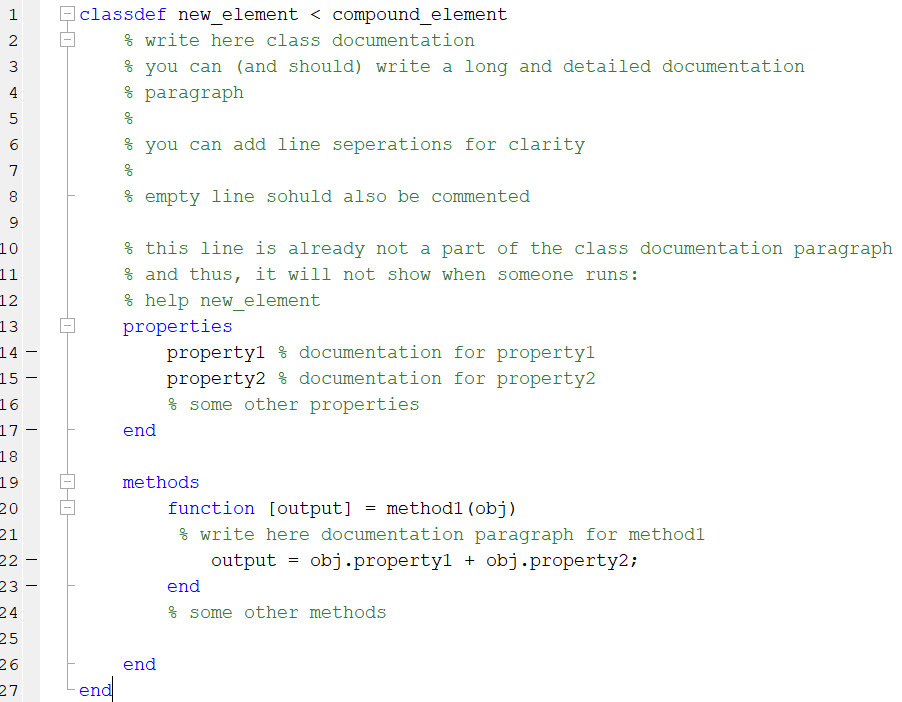

### 1.2 what should be included in the documentation paragraph

the documentation paragpraphs for any element should include:

- a description of the element

- a list of all the input arguments of the constructor, what sould be thier type, what is their meaning, are they optional and what is the default values. in complicated cases it is also recommended to add example of call to the constructor

- a list of all the element's ports and thier significance

for example, see the documentation paragraph for the knee_resonator:

help knee_resonator

  written by Guy and Samuel. editted by Guy 09/10/20
  a coplanar resonator with length total_l, and a knee-type coupling
  of length coupling_l.
 
  input arguments for ctor:
 
  required arguments:
    total_l - total length of resonator
    coupling_l = length of coupling segment
 
  optional parameters (call with name-value pair ot input a struct):
    trace_w: width of the trace (metal) . default value: 8
    gap_w: width of the gap (insulator . default value: 5
    segment_l : the length of the bulk N-2 segments of the meander. there
                are another two segments of length segmentl/2 in the input and in the
                output. default value: 500
    distance : the distance between the segments ( = the diameter of the
    arcs). default value: 200
 
    to make a tight-meander , set distance = trace_w + gap_w;
 
  ports:
  input - the end of the coupling knee
  output - the other end of the resonator
  center - the center of the meander.

    

the documentation paragraph for any method or function should include:

- a description of what the method does

- a list of all input arguments detailing thier type, their significance, required/optional (+ default value).

-  what does the fucntion return

## 2. names and conventions

I think it will be nice to stick with the same kind of naming conventions. the conventions I use are:

- everything is lowercase

- use underscore  for seperation. e.g. trace_w, compound_element, shift_vec, etc..

- long and meaningfull is  better than short and ambiguous. e.g coplanar_resonator and not cop_res.

## 3. Input arguments for constructors

I think in general there shouldn't be more than 3-4 required input arguments for any constructor. if the design has more parameters than that,  it is better to make them optional parameners with default values. see for example the knee resonator:

we can create one by only defining the total length and the coupling length:

res=knee_resonator(6000,200)

other parameters like trace_w, gap_w etc.. are defined automatically to default values. if we want a resonator with central trace of 16 um and gap of 10  um for example we can do it like this:

res = knee_resonator(6000,200, 'trace_w', 16,'gap_w', 10)

or like this:

my_res_params.trace_w = 16;
my_res_params.gap_w = 10;
res = knee_resonator(6000,200,my_res_params)

To learn how to program this behavior  in matlab functions see: [https://www.mathworks.com/help/matlab/ref/inputparser.html](https://www.mathworks.com/help/matlab/ref/inputparser.html)